# SINDy PDE find: Kuramoto-Sivashinsky equation

Kuramoto-Sivashinsky equation: $\partial_t \;u+u\partial_x \;u+\partial_x^2 \;u+\partial_x^4 \;u=0$

KS equation describes: 

- chaotic dynamics of laminar flame fronts: G. Sivashinsky, Nonlinear analysis of hydrodynamic instability in laminar flames: I. derivation of basic equations, Acta Astronaut. 4, 1177 (1977).

- reaction-diffusion systems: Y. Kuramoto and T. Tsuzuki, Persistent propagation of concentration waves in dissipative media far from thermal equilibrium, Prog. Theor. Phys. 55, 356 (1976).

- coating flows: G. I. Sivashinsky and D. Michelson, On irregular wavy flow of a liquid film down a vertical plane, Prog. Theor. Phys. 63, 2112 (1980).

Data and code (modified) from Rudy et al (2017) and Reinbold et al (2020).

- Paper Rudy: [https://www.science.org/doi/10.1126/sciadv.1602614](https://www.science.org/doi/10.1126/sciadv.1602614) 

- Github Rudy: [https://github.com/snagcliffs/PDE-FIND](https://github.com/snagcliffs/PDE-FIND) 

- Paper Reinbold: [https://journals.aps.org/pre/pdf/10.1103/PhysRevE.101.010203](https://journals.aps.org/pre/pdf/10.1103/PhysRevE.101.010203) 

- Github Reinbold: [https://github.com/pakreinbold/PDE_Discovery_Weak_Formulation](https://github.com/pakreinbold/PDE_Discovery_Weak_Formulation)   

## Load Kuramoto-Sivashinsky data

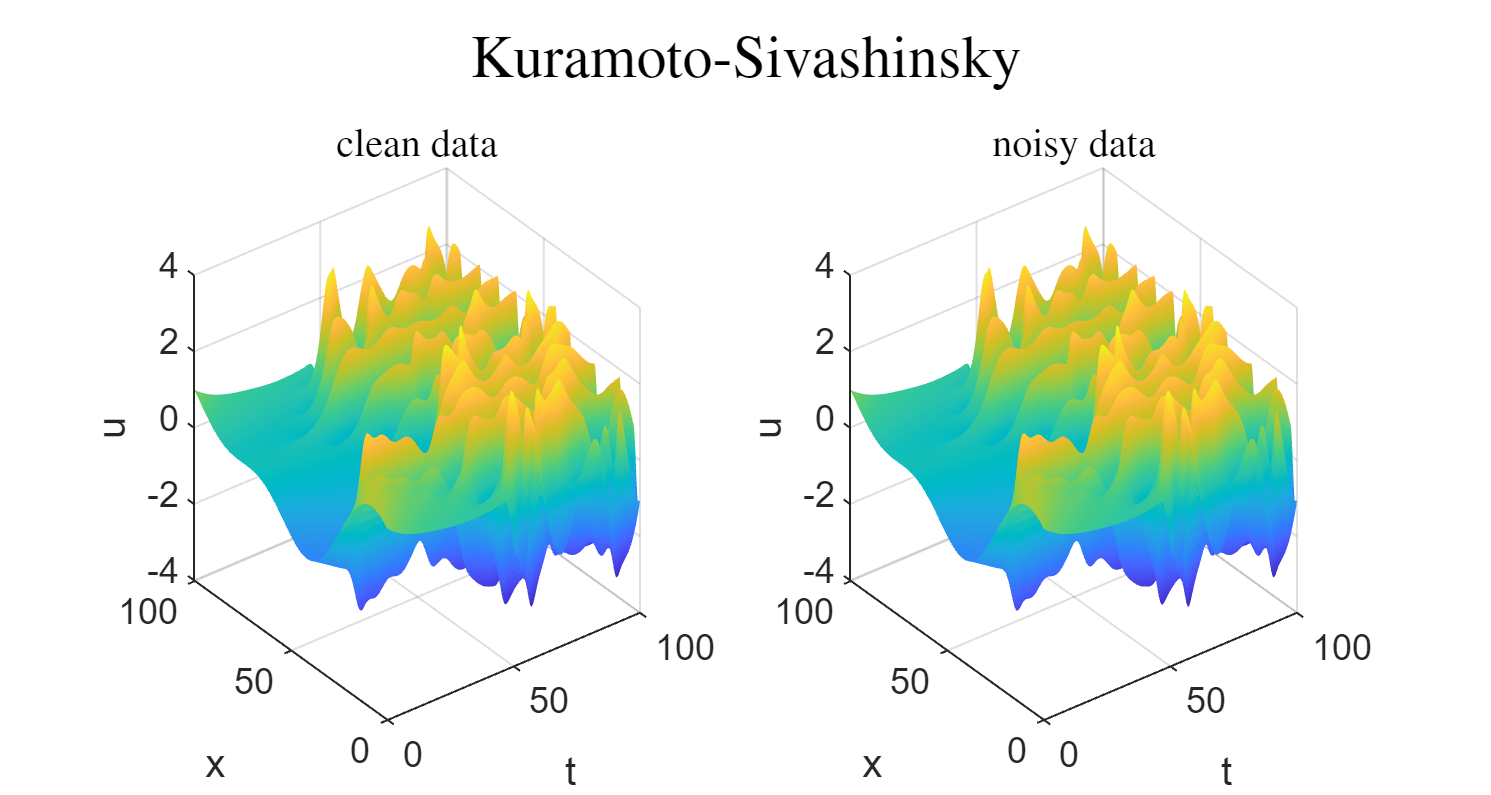

addpath(genpath(pwd))

% load data
traj = matfile('KS_data'); 

% grid densities
dt = traj.dt;
dx = traj.dx; 

% add noise
sig = 0.0;
% sig = 0.01;

Ua = traj.uu; 
Ua = Ua + sig*std(Ua(:))*randn(size(Ua)); % Gaussian

% plot data
plotPDEdata(traj,Ua,'Kuramoto-Sivashinsky')

## Identify PDE 

%% compute derivatives using finite difference
ut=[];
for xpos=1:size(Ua,1)
    ut(xpos,:)=FiniteDiff(real(Ua(xpos,:)),dt,1);
end

ux=[];uxx=[];uxxx=[];uxxxx=[];
for kk=1:size(Ua,2)
    ux(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,1);
    uxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,2);
    uxxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,3);
    uxxxx(:,kk)=FiniteDiff(real(Ua(:,kk)),dx,4);
end


%% build library

%% time derivatives: left hand side
LHS = -ut(:);

%% Library Theta: right hand side
const = ones(traj.Nt,traj.Nx);
u = Ua;
u2 = Ua.^2; 
u3 = Ua.^3;
% first order derivative ux 
uux = Ua.*ux; % advection term
u2ux = Ua.^2.*ux;
u3ux = Ua.^3.*ux;
% second order derivative uxx: Laplacian 
uuxx = Ua.*uxx;
u2uxx = Ua.^2.*uxx;
u3uxx = Ua.^3.*uxx;
% third order derivative uxxx
uuxxx = Ua.*uxxx;
u2uxxx = Ua.^2.*uxxx;
u3uxxx = Ua.^3.*uxxx;
% fourth order derivative: Biharmonic 
uuxxxx = Ua.*uxxxx;
u2uxxxx = Ua.^2.*uxxxx;
u3uxxxx = Ua.^3.*uxxxx;

Theta = [const(:), u(:), u2(:), u3(:), ux(:), uux(:), u2ux(:), u3ux(:), uxx(:), uuxx(:), u2uxx(:), u3uxx(:), uxxx(:), uuxxx(:), u2uxxx(:), u3uxxx(:), uxxxx(:), uuxxxx(:), u2uxxxx(:), u3uxxxx(:),];


%% SINDy using sequential thresholded least squares
n = 1; % number of states
lambda = 0.05; % sparsification knob
Xi = sparsifyDynamics(Theta,LHS,lambda,n); % SINDy

% print coefficients
ThetaLIST = {'1','u','u^2','u^3','u_{x}','uu_{x}','u^2u_{x}','u^3u_{x}','u_{xx}','uu_{xx}','u^2u_{xx}','u^3u_{xx}','u_{xxx}','uu_{xxx}','u^2u_{xxx}','u^3u_{xxx}','u_{xxxx}','uu_{xxxx}','u^2u_{xxxx}','u^3u_{xxxx}'}';
Xi_SINDy = [ThetaLIST, num2cell(Xi)]

Xi_SINDy = 20×2 cell array
    {'1'         }    {[     0]}
    {'u'         }    {[     0]}
    {'u^2'       }    {[     0]}
    {'u^3'       }    {[     0]}
    {'u_{x}'     }    {[     0]}
    {'uu_{x}'    }    {[0.9846]}
    {'u^2u_{x}'  }    {[     0]}
    {'u^3u_{x}'  }    {[     0]}
    {'u_{xx}'    }    {[0.9944]}
    {'uu_{xx}'   }    {[     0]}
    {'u^2u_{xx}' }    {[     0]}
    {'u^3u_{xx}' }    {[     0]}
    {'u_{xxx}'   }    {[     0]}
    {'uu_{xxx}'  }    {[     0]}
    {'u^2u_{xxx}'}    {[     0]}
    {'u^3u_{xxx}'}    {[     0]}



% error
c = ones(3,1); % KS true model coefficients
XiTrue = Xi([6 9 17]); % KS true model structure
error_SINDy = abs(XiTrue-c)./c % model coefficient error

error_SINDy =     0.0154
    0.0056
    0.0010


nonZeroTermsSINDy = nnz(Xi) % number of nonzeros

nonZeroTermsSINDy = 3